# **Modeling of Passive Solar House in Boston, MA**

## **I**ntroduction and Background

#### What is a passive solar home?

Passive solar houses are incredible. By definition passive solar houses they use energy from the sun and their surroundings to maintain a livable internal temperature. Everyone should be interested in building one as passive homes are much cheaper to heat and cool since they are designed in such a way to naturally maintain reasonable temperatures. 

Passive solar homes are built on the principle of storing energy from the sun. At a base level they require: 

- A large thermal mass (like stone floors) to store energy from the sun

- Large south facing windows to collect sun, specifically in the winter months

- Some form of insulation to reduce heat loss

- Other controls/design choices to block sun in certain situations (eaves, trees, etc)

#### What's our strategy?

Designing a passive solar house for the Boston area where it gets very cold in the winter will require careful design of the house. In attempt to maintain a stable internal temperature, our first model/design will incorporate the following features:

- Extremely large south facing window

- Eaves that protect the windows/thermal mass during the summer

- A tile floor that act's as a large thermal mass

- No windows in any other walls

- A very tiny floorplan (~200sqft)

- Insulation in the ceiling, walls, and floor

## Modeling

Our house can be simplified down to a very simple resistance network. We abstract the floor as the heat capacity for the entire house, the walls as purely insulation, and the window size as a control of the amount of energy coming into the house. Below is our resistance network modeled like a circuit.

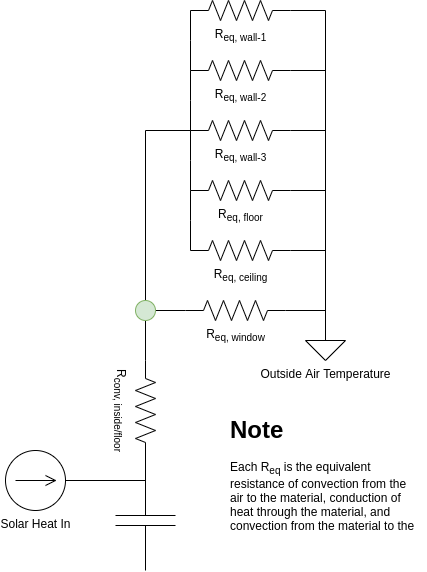

#### Assumptions

Key assumptions allow the simplification of this complex system to the above network. These include:

- Air doesn't enter or leave the house

- Insulation (the walls) is purely a resistance, and doens't store any heat

- The only heat storage is in the large thermal mass (floor)

- Radiation only hits the window and the heat storage unit

- All radiation through window hits the heat storage unit

- Heat transfer and resistance is the same for all walls, floors, and ceilings of the same materials

- Heat storage unit is at spatially uniform temperature

These assumptions are justified. 

- Air doesn't have a large thermal mass, and won't exchange much if windows etc aren't opened

- Insulation has a much lower heat capacity than the floor

- Radiation in Boston in winter will not change internal temp much, also very complex to implement

- If the window is designed properly than it is possible that most of the sunlight hit's the thermal mass

- The change in materials/properties for cieling/walls, would add complexity but would be hard to verify/produce better results

- The floor should heat up close to uniformly. This simplifies the heat transfer more than it detracts from the accuracy of the model. It would be extremely difficult to model differently

#### Governing  ODE's

The simplification of this house makes it possible to model behavior of the various parts of the house by using an Ordinary Differential Equation.

This simple house makes use of just one ODE, it describes the rate of change of the temperature of the floor ($T_{floor}$) in realtion to time. This value depends on the amount of energy coming into the floor via solar radiation ($Q_{in}$). The floor also loses energy to its surroundings through the air and then the walls. This rate is influenced by the temperature differential between the outside and inside air and the overall resistance that is calculated from the geometry and materials of the house.

*ODE describing rate of change of the Temp of the floor*


$$\frac{dT_{floor}}{dt} =\frac{Q_{in}}{C_{floor}} - \frac{ T_{floor}-T_{out}}  {C_{floor}\cdot R_{total}} $$


When designing a passive solar house, one of the most important things to look at is the internal air temperature. The inside air temperature can be modeled as a linear function of the floor temperature.

*Realtionship between the Temp of the air inside the house and the floor*


$$T_{inside\ air} = \frac{R_{parallel}}{R_{total}}\cdot T_{floor}
$$
 

### Parameters

#### Time

% Number of days to run the model
days = 14;

% Timespan for the model
step_size = 60;
time_span = [0:step_size:60*60*24*days];

#### Dimensions

A helper function is used to calculate all of the different parameters of the house.

The final parameters we used are a floor thickness of 0.275 meters, an insulation thickness of 5.125cm, and a window border of 0.5m (amount of space on either side of the window made of insulation).

[house insulation floor window R outside_air inside_air, Qin] = calculate_constants(0.275,.05125,0.5) %Floor Thick, Insul Thick, Window border(larger number makes window smaller)

house = struct with fields:
                        x: 5
                        y: 3
                        z: 5
                    sq_ft: 269.0975
                     eave: 0.9000
       ceiling_floor_area: 25
           side_wall_area: 15
    anti_window_wall_area: 15
         window_wall_area: 6


insulation = struct with fields:
     thickness: 0.0512
             k: 0.0400
    total_area: 101


floor = struct with fields:
            x: 5
            z: 5
            y: 0.2750
      density: 3000
    spec_heat: 800
         mass: 20625
          T_0: 0
           sa: 55.5000
      heat_in: []
     heat_cap: 16500000


window = struct with fields:
           h: 0.7000
           y: 2
           z: 4.5000
        area: 9
    y_offset: 0.2000


R = struct with fields:
          air_wall: 6.6007e-04
              wall: 0.0127
      wall_outside: 3.3003e-04
        wall_total: 0.0137
        air_window: 0.0074
            window: 0.1587
    window_outside: 0.0037
      window_total: 0.1698
              loss: 0.0127
         floor_air: 0.0012
             total: 0.0139


outside_air = struct with fields:
      T: -3
      h: 30
    sin: @(t)(-3+6*sin((2*pi*t)/(24*60*60)+(3*pi)/4))


inside_air = struct with fields:
    T_0: 0
      h: 15


Qin = function_handle with value:
    @(t)(-361*cos((pi*t)/(12*3600))+224*cos((pi*t)/(6*3600))+210)*window.area


### ODEs and other Relationships

*ODE describing rate of change of the Temp of the floor*


$$\frac{dT_{floor}}{dt} =\frac{Q_{in}}{C_{floor}} - \frac{ T_{floor}-T_{out}}  {C_{floor}\cdot R_{total}} $$


*Relationship describing rate of change of the Temp of the air inside the house*


$$T_{inside\ air} = \frac{R_{parallel}}{R_{total}}\cdot T_{floor}
$$
 

### First pass model with constant outside temperature

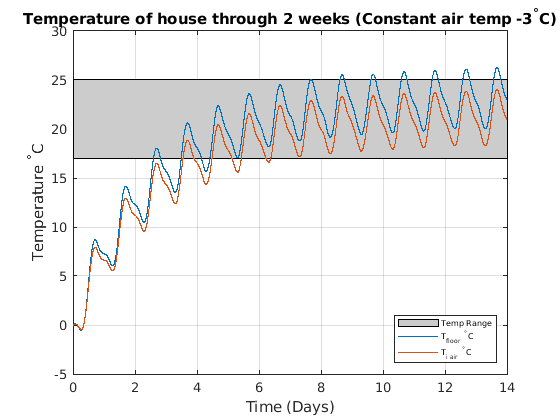

% Set up and solve ODEs
f = @(t,T) Qin(t)/floor.heat_cap - (T(1)-outside_air.T)/(R.total*floor.heat_cap);
[t,T_sol] = ode45(f,time_span,[0]);

% Compute inside air temperature using voltage divider analogy
T_sol(:,2) = T_sol(:, 1) * (R.loss/R.total);

% Plot
figure
plot_ode(t, T_sol, true)
final_touches_plot()
title("Temperature of house through 2 weeks (Constant air temp -3^{\circ}C)")

### Second pass model with outside temperature as a sin function

% Set up and solve ODEs
f = @(t,T) Qin(t)/floor.heat_cap - (T(1)-outside_air.sin(t))/(R.total*floor.heat_cap);
[t_sin,T_sol_sin] = ode45(f,time_span,[0]);

% Compute inside air temperature using voltage divider analogy
T_sol_sin(:,2) = T_sol_sin(:, 1) * (R.loss/R.total);

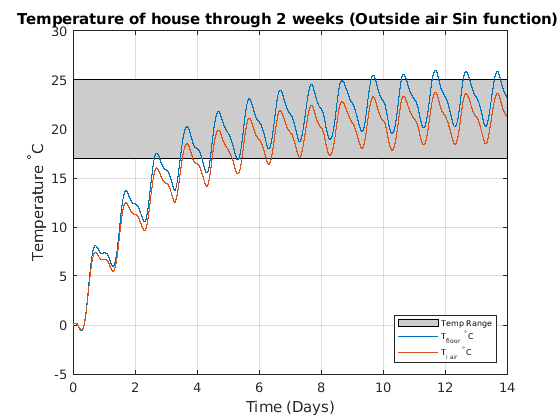

figure
plot_ode(t_sin, T_sol_sin, true)
final_touches_plot()
title("Temperature of house through 2 weeks (Outside air Sin function) ")

The above plot shows the house's temperature as a function of time. The shaded region represents the desired range of temperature for a day. The house takes several days to warm up before it stables in a region within our desired range of 17-25. These reults are obtained by using Matlab's ode45 solver to solve our differential equation.

### Optimization

values = 5;
min_insul = 0.045;
max_insul = 0.07;
min_floor_thick = 0.15;
max_floor_thick = 0.4;
min_win = 1;
max_win = 0;% Window is ntire width of house
insul_range = linspace(min_insul, max_insul, values);
floor_range = linspace(min_floor_thick, max_floor_thick, values);
win_range = linspace(min_win, max_win, 3);

plot_num = 1;
x = linspace(0,10);
figure1=figure('Position', [100, 100, 4000, 4000]);
for i = insul_range
    for k = floor_range
        %Set appropriate values
        subplot(values,values,plot_num)
        for w = win_range
            [house insulation floor window R outside_air inside_air, Qin] = calculate_constants(k, i, w);
            f = @(t,T) [Qin(t)/floor.heat_cap - (T(1)-outside_air.sin(t))/(R.total*floor.heat_cap);];
            [t_sin,T_sol_sin] = ode45(f,time_span,[0]);
            T_sol_sin(:,2) = T_sol_sin(:, 1) * (R.loss/R.total); % Use voltage divider analogy to calculate internal air temp    
            plot_ode(t_sin, T_sol_sin, false, window.area)
        end
        final_touches_plot(true)
        title( k + "m floor, " + i + "m insul")
        
%         
%         y1 = 10*i*sin(x)+k;
%         plot(x,y1)
%         title("Subplot"+ plot_num + ": sin(x)")
        plot_num = plot_num + 1;
    end
    
end
han=axes(figure1,'visible','off'); 
han.Legend

ans =   0×0 empty GraphicsPlaceholder array.


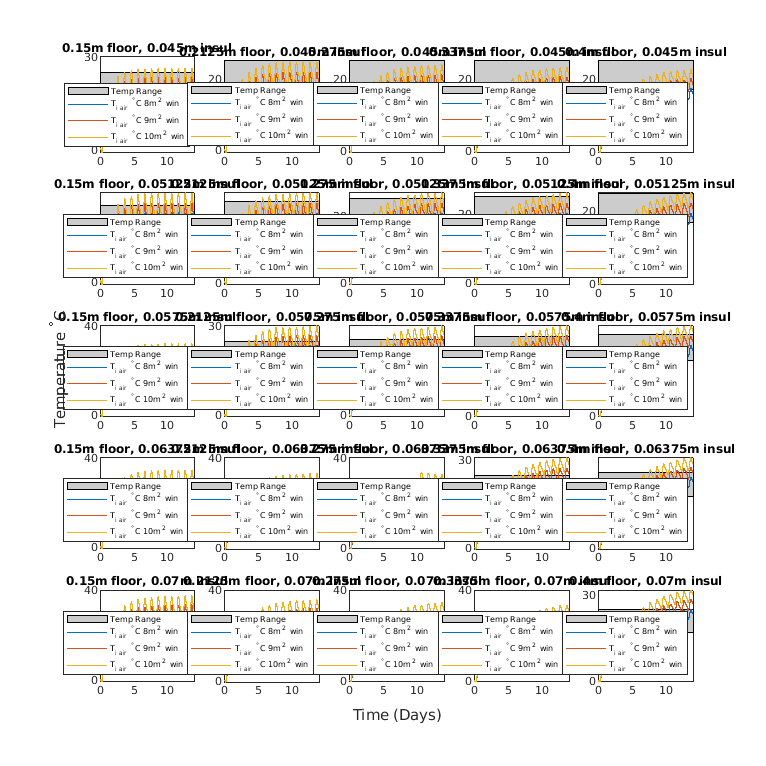

han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
xlabel("Time (Days)");
ylabel("Temperature ^{\circ}C");

### Results and discussion

#### Single day

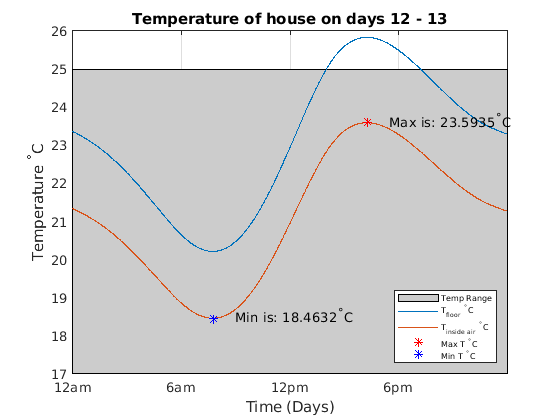

% Fetch the constants we used in our final model once more
[house insulation floor window R outside_air inside_air, Qin] = calculate_constants(0.275,.05125,0.5);

% Re-set up and solve ODEs
f = @(t,T) [Qin(t)/floor.heat_cap - (T(1)-outside_air.sin(t))/(R.total*floor.heat_cap);];
[t_sin,T_sol_sin] = ode45(f,time_span,[0]);

% Re-compute inside air temperature using voltage divider analogy
T_sol_sin(:,2) = T_sol_sin(:, 1) * (R.loss/R.total);

day_start = 12;
day_end = 13;
day_ticks = ["12am","6am","12pm","6pm",];
seconds_in_day = 24*3600/step_size;
day_start_index = 1+day_start*seconds_in_day;
day_end_index = day_end*seconds_in_day;

figure
plot(t_sin(day_start_index:day_end_index,:)/(60*60*24), T_sol_sin(day_start_index:day_end_index,1), "DisplayName", "T_{floor} ^{\circ}C");
hold on;
plot(t_sin(day_start_index:day_end_index,:)/(60*60*24), T_sol_sin(day_start_index:day_end_index,2), "DisplayName", "T_{inside air} ^{\circ}C");

[maxVal,maxIDX] = max(T_sol_sin(day_start_index:day_end_index,2));
[minVal,minIDX] = min(T_sol_sin(day_start_index:day_end_index,2));
% % % for single point plotting, use scatter
scatter((t_sin(day_start_index+maxIDX))/(60*60*24), maxVal, '*r', "DisplayName", "Max T ^{\circ}C")
scatter((t_sin(day_start_index+minIDX))/(60*60*24), minVal, '*b', "DisplayName", "Min T ^{\circ}C")

dx = 0.05; dy = 0.05; % displacement so the text does not overlay the data points
text((t_sin(day_start_index+maxIDX))/(60*60*24)+dx, maxVal+dy, "Max is: "+ maxVal + "^{\circ}C");
text((t_sin(day_start_index+minIDX))/(60*60*24)+dx, minVal+dy, "Min is: "+ minVal + "^{\circ}C");

final_touches_plot
xticks(day_start:1/4:day_end)
xticklabels(repmat(day_ticks, 1, day_end-day_start));
%xticklabels(["Midnight","6am","Noon","6pm","Midnight"])
% find max of Ethanol
title("Temperature of house on days " + day_start + " - " + day_end)

This house has a large range of temperature throughout the day. This house has a larger temperature change daily (18.5-23.5*C) than most houses. Typical temperatures for houses are between 20-22*C. This simply means that our house changes temperature more than a typical house. 

https://en.wikipedia.org/wiki/Room_temperature

### Analyzing heat absorbed through the window for one day and temperature change

We were concerned with how hot our floor/house was getting (~60*C). To take a look at possible explanations for this behavior we wanted to look at how much energy was coming into the house. 


$$Q_{in} = (-361 \cdot \cos(\frac {t\pi}{12 \cdot 3600}) + 224 \cdot \cos(\frac {t\pi}{6 \cdot 3600}) + 210) \cdot A_{window.area}$$


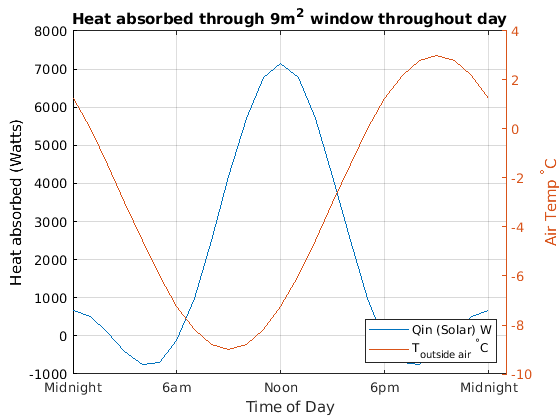

% Calculate and plot the solar heat and outside air temp for one day
one_day = [0 : 60*60 : 24*3600]; % Calculated each hour
solar_day = Qin(one_day);
out_air = outside_air.sin(one_day);

figure
plot(one_day/3600, solar_day, "DisplayName", "Qin (Solar) W");
yyaxis right
plot(one_day/3600, out_air , "DisplayName", "T_{outside air} ^{\circ}C");
xticks([0,6,12,18,24]);
xticklabels([["Midnight","6am","Noon","6pm","Midnight"]])
grid on; legend("Location", "Southeast");
xlabel("Time of Day")
ylabel("Air Temp ^{\circ}C")
yyaxis left
ylabel("Heat absorbed (Watts)")
title("Heat absorbed through " + window.area + "m^2 window throughout day")

This plot shows the amount of energy coming into the house at various points of the day for our given window size. It also shows the outside temperature of the house throughout the day. Together, these curves explain the shape of the floor temperature curve seen in one day.

At it's peak, there is ~10,000 watts coming into the house. This value seemed really high at first! However, according to some sources, this is likely realistic. Tennessee Solar info indicates that at the surface of the earth in good conditions solar flux could be around ~1000 w/m^2. Our window is 13m^2 which indicates that our max solar flux is < 1000W/m^2 and is likely within an acceptable range.

## Bibliography

If we had had more time, there are a number of project extensions we had considered. It would have been interesting to programmatically calculate the best values for our parameters. These parameters would heat up the house quickly initially, and keep the temperature within our range of values with smaller fluctuations throughout the day. We could accomplish this using a gradient descent model, where our reward function is the min and max temperature, and the goal would be to keep it in the 18-25 degree celcius range with minimal fluctuations, and using reasonable domains for the parameters so that we don't get a 10 meter thick floor.

Sections

- *Background*

- *Model*

- *Optim*

- Discussion

- Bib

## Bibliography

function a = plot_ode(x,y, both, win_area)
    if nargin<4
        % Then no window area was supplied
        text = "";
    else
        text = win_area + "m^2 win";
    end
    
    if both 
        plot(x/(60*60*24), y(:,1), "DisplayName", "T_{floor} ^{\circ}C " + text);
        hold on;
    end
    plot(x/(60*60*24), y(:,2), "DisplayName", "T_{i air} ^{\circ}C " + text);
    hold on
end
function a = final_touches_plot(noaxis)
    if nargin<1
        % Then no window area was supplied
        noaxis = false;
    end
    ybars = [17 25];
    p = patch([min(xlim) max(xlim) max(xlim) min(xlim)], [ybars(1) ybars(1), ybars(2) ybars(2)], [0.8 0.8 0.8], "DisplayName", "Temp Range");
    uistack(p, "bottom");
    if noaxis
        
    else
       add_axis
    end
    add_legend
    hold off
end

function a = add_axis()
    grid on;     
    xlabel("Time (Days)");
    ylabel("Temperature ^{\circ}C");
end
function a = add_legend()
    lgd = legend("Location", "Southeast");
    lgd.FontSize = 6;
end

function [house, insulation, floor, window, R, outside_air, inside_air, Qin] = calculate_constants(floor_thick, insul_thick, window_offset)
    if nargin<3
      floor_thick = 0.275;
      insul_thick = 0.0575;
      window_offset = 0.5;
    end
    global time_span
    % Internal dimensions of inside air
    house.x = 5.0; % meters
    house.y = 3.0; % meters
    house.z = 5.0; % meters
    house.sq_ft = house.x * house.z * 10.7639; % ft^2
    house.eave = 0.9; % m % Length of the eave of the house
    
    % Window
    window.h = 0.7;
    window.y = 2.0; % m;
    window.z = house.z-window_offset; % m % Window has a half meter wall on either side
    window.area = window.y * window.z; % m^2
    window.y_offset = 0.2; % m % Height off the ground
    
    % Floor
    floor.x = house.x;
    floor.z = house.z;
    % PARAM %
    floor.y = floor_thick; % meters
    floor.density = 3000.0; % kg/m^3
    floor.spec_heat = 800.0; % J/kg*K
    floor.mass = floor.x * floor.y * floor.z * floor.density; % kg
    floor.T_0 = 0; % C
    floor.sa = 2*floor.x*floor.y + 2*floor.x*floor.z + 2*floor.y*floor.z; % m^2 % Surface area
    
    % Walls
    house.ceiling_floor_area = house.z * house.x; % m^2
    house.side_wall_area = house.x * house.y; % m^2
    house.anti_window_wall_area = house.z * house.y; % m^2 % Wall opposite window
    house.window_wall_area = house.anti_window_wall_area - (window.area); % m^2 % WHY DO WE NEED THIS LAST PART??
    
    % PARAM %
    insulation.thickness = insul_thick; % meters
    insulation.k = 0.04; % W/m*K % Thermal conductivity constant
    insulation.total_area = 2*house.ceiling_floor_area + 2*house.side_wall_area + house.anti_window_wall_area + house.window_wall_area; % m^2

#### Air Temperature

    outside_air.T = -3; % degrees celcius
    outside_air.h = 30.0; % W/m^2*K


$$T_{outside\ air} = -3 + 6 \cdot \sin(\frac{2t\pi}{24 \cdot60\cdot60}) + \frac{3\pi}{4}$$


    outside_air.sin = @(t) (-3 + 6*sin((2*pi*t)/(24*60*60) + (3*pi)/4)); % Degrees celcius
    
    inside_air.T_0 = 0; % degrees celcius
    inside_air.h = 15.0; % W/m^2*K

#### Heat

    % W/m^2
    solar_flux = -361 .* cos((pi.*time_span)./(12*3600)) + 224 .* cos((pi.*time_span)./(6*3600)) + 210;
    floor.heat_in = solar_flux .* window.area; % W
    Qin = @(t) (-361 * cos((pi*t)/(12*3600)) + 224 * cos((pi*t)/(6*3600)) + 210) * window.area;

### Resistances/Capacities

    floor.heat_cap = floor.spec_heat * floor.mass; % J/K
    
    % Resistance through all the insulation
    R.air_wall = (inside_air.h * insulation.total_area)^-1; % Convection, K/W
    R.wall = insulation.thickness / (insulation.k * insulation.total_area); % Conduction, K/W
    R.wall_outside = (outside_air.h * insulation.total_area)^-1; % Convection, K/W
    R.wall_total = R.air_wall + R.wall + R.wall_outside; % K/W
    
    % Resistance through the window
    R.air_window = (inside_air.h * window.area)^-1; % Convection, K/W
    R.window = (window.h * window.area)^-1; % Conduction, K/W
    R.window_outside = (outside_air.h * window.area)^-1; % Convection, K/W
    R.window_total = R.air_window + R.window + R.window_outside; % K/W
    
    R.loss = (sum([R.wall_total R.window_total].^-1))^-1;
    
    R.floor_air = (inside_air.h*floor.sa)^-1; % Resistance from floor to inside air
    
    R.total = R.floor_air + R.loss; % Total resistance from floor to outside air
end